# MATLABによるテキストマイニングビデオシリーズ

本スクリプトは、[MATLABによるテキストマイニングビデオシリーズ](https://www.mathworks.com/videos/series/text-mining-with-matlab-video-series.html)のPart2で紹介している処理をまとめています。宜しければビデオの方も併せてご覧ください。

Copyright 2020 The MathWorks, Inc.

以下では、ウェブサイト上のテキストを読み込みます。

URLを指定し、[webread](https://jp.mathworks.com/help/matlab/ref/webread.html)関数でコンテンツを読み取ります。HTMLタグが混ざったテキストが返って来ていることが判ります。

url = 'https://blogs.mathworks.com/japan-community/2020/08/05/three-reasons-why-i-use-matlab-for-text-analytics/';
txt = webread(url)

[htmlTree](https://jp.mathworks.com/help/textanalytics/ref/htmltree.html)関数と[extractHTMLText](https://jp.mathworks.com/help/textanalytics/ref/htmltree.extracthtmltext.html)関数を使用して、不要なタグを取り除きます。

tree = htmlTree(txt)

tree =   htmlTree:

   <HTML lang="en">
       <HEAD>
           <META content="IE=edge" http-equiv="x-ua-compatible"/>
           <!-- Start wp_head -->
           <!-- All in One SEO Pack 2.2.5.1 by Michael Torbert of Semper Fi Web Design[,] -->
           <META
               content="MATLABのテキスト解析用ツールや、MATLABでテキスト解析を行う魅力について紹介します。テキスト解析をやってみたい方の参考になれば幸いです。"
               itemprop="description" name="description"/>
           <META
               content="matlab,自然言語処理,テキスト解析,形態素解析,mecab,ディープラーニング,構文解析,意味解析,sentiment analysis,分散表現,トピックモデル,機械翻訳,cabocha,cotoha"
               itemprop="keywords" name="keywords"/>
           <LINK
               href="https://blogs.mathworks.com/japan-community/2020/08/05/three-reasons-why-i-use-matlab-for-text-analytics/" rel="canonical"/>
           <!-- /all in one seo pack -->
           <LINK href="//s.w.org" rel="dns-prefetch"/>
           <LINK
               href="https://blogs.m

str = extractHTMLText(tree)

str =     "本日は、MathWorks Japanでデータサイエンス関係を広く担当している田口さんに、自然言語処理について投稿して頂きます。記事をヒントに是非遊んでみてください！
     
     —
     
     こんにちは。アプリケーションエンジニアリング部の田口と申します。今回ゲストブロガーとして、単発ですが記事を書かせていただきます。普段は機械学習、ディープラーニングといった分野でお客様の技術サポートをさせて頂いています。また、その中でも、テキスト解析や医療データ解析、強化学習といった技術のサポートに特に注力しています。
     
     私事で恐縮なのですが、7 月にディープラーニングG検定なるものを受験しまして、難しかったーという感想はさておき、結構テキスト解析や強化学習の分野からの出題が多かったなぁと感じています。正直、少し前までは、テキスト解析がどんな風に使えるのかあまりイメージが湧かなかったと思います。しかし、最近では有名なところだと、Google 翻訳や Siri といったサービスもありますし、ロボティクスでマルチモーダル解析（画像・音声・テキスト等をまとめて解析）を行うという文脈でテキスト解析が登場するようです。そんなこともあって、テキスト解析は近頃ますますホットなトピックなのではとお見受けしています。
     
     そこで今日は、MATLAB の Text Analytics Toolbox について、MATLAB でテキスト解析を行う魅力について個人的な視点から語りたいと思います！テキスト解析に興味のある方、テキスト解析のツールを選定中の方や、MATLAB のテキスト解析でできることを日本語でざっと確認したい方など少しでもお役に立てたら嬉しいです。テキスト解析の専門用語も出てきますが、用語についての説明は省略していますのでその点はご了承ください。
     
     【目次】
     
     解析環境のセットアップが簡単
     
     解析が簡単
     
     小回りが利く
     
     １．解析環境のセットアップが簡単
     
     これからテキスト解析を始めたいという方には朗報ですが、Text Analytics Toolbox では解析環境のセットアップが非常に

[tokenizedDocument](https://jp.mathworks.com/help/textanalytics/ref/tokenizeddocument.html)関数を使用して、文章をトークン化します。

documents = tokenizedDocument(str)

documents =   tokenizedDocument:

   2307 個のトークン: 本日 は 、 MathWorks Japan で データ サイエンス 関係 を 広く 担当 し て いる 田口 さん に 、 自然 言語 処理 について 投稿 し て 頂き ます 。 記事 を ヒント に 是非 遊ん で み て ください ！ — こんにちは 。 アプリケーション エンジニアリング 部 の 田口 と 申し ます 。 今回 ゲストブロガー として 、 単発 です が 記事 を 書か せ て いただき ます 。 普段 は 機械 学習 、 ディープラーニング といった 分野 で お客様 の 技術 サポート を さ せ て 頂い て い ます 。 また 、 その 中 でも 、 テキスト 解析 や 医療 データ 解析 、 強化 学習 といった 技術 の サポート に 特に 注力 し て い ます 。 私事 で 恐縮 な の です が 、 7 月 に ディープラーニング G 検定 なる もの を 受験 し まし て 、 難しかっ た ー という 感想 は さておき 、 結構 テキスト 解析 や 強化 学習 の 分野 から の 出題 が 多かっ た なぁ と 感じ て い ます 。 正直 、 少し 前 まで は 、 テキスト 解析 が どんな 風 に 使える の か あまり イメージ が 湧か なかっ た と 思い ます 。 しかし 、 最近 で は 有名 な ところ だ と 、 Google 翻訳 や Siri といった サービス も あり ます し 、 ロボティクス で マルチモーダル 解析 （ 画像 ・ 音声 ・ テキスト 等 を まとめ て 解析 ） を 行う という 文脈 で テキスト 解析 が 登場 する よう です 。 そんな こと も あっ て 、 テキスト 解析 は 近頃 ますます ホット な トピック な の で は と お 見受け し て い ます 。 そこで 今日 は 、 MATLAB の Text Analytics Toolbox について 、 MATLAB で テキスト 解析 を 行う 魅力

[removeStopWords](https://jp.mathworks.com/help/textanalytics/ref/tokenizeddocument.removestopwords.html)関数、[erasePunctuation](https://jp.mathworks.com/help/textanalytics/ref/tokenizeddocument.erasepunctuation.html)関数、[normalizeWords](https://jp.mathworks.com/help/textanalytics/ref/normalizewords.html)関数を使用してテキストのクリーニングを行います。その他のデータクリーニング関数については[こちら](https://jp.mathworks.com/help/textanalytics/text-data-preparation.html)からご確認ください。

documents = removeStopWords(documents)

documents =   tokenizedDocument:

   1298 個のトークン: 本日 、 MathWorks Japan データ サイエンス 広く 担当 田口 、 自然 言語 処理 について 投稿 頂き 。 記事 ヒント 是非 遊ん み ください ！ — こんにちは 。 アプリケーション エンジニアリング 田口 申し 。 ゲストブロガー として 、 単発 記事 書か せ いただき 。 普段 機械 学習 、 ディープラーニング といった 分野 お客様 技術 サポート せ 頂い 。 、 、 テキスト 解析 医療 データ 解析 、 強化 学習 といった 技術 サポート 特に 注力 。 私事 恐縮 、 7 ディープラーニング G 検定 受験 、 難しかっ ー という 感想 さておき 、 結構 テキスト 解析 強化 学習 分野 出題 多かっ なぁ 。 正直 、 少し 、 テキスト 解析 どんな 風 使える あまり イメージ 湧か なかっ 思い 。 しかし 、 最近 有名 、 Google 翻訳 Siri といった サービス 、 ロボティクス マルチモーダル 解析 （ 画像 ・ 音声 ・ テキスト まとめ 解析 ） 行う という 文脈 テキスト 解析 登場 。 そんな あっ 、 テキスト 解析 近頃 ますます ホット トピック 見受け 。 そこで 今日 、 MATLAB Text Analytics Toolbox について 、 MATLAB テキスト 解析 行う 魅力 について 個人 視点 語り 思い ！ テキスト 解析 興味 、 テキスト 解析 ツール 選定 、 MATLAB テキスト 解析 できる 日本語 ざっと 確認 少し 役 立て たら 嬉しい 。 テキスト 解析 専門 用語 出 き 、 用語 について 説明 省略 ご 了承 ください 。 【 目次 】 解析 環境 セットアップ 簡単 解析 簡単 小回り 利く １ ． 解析 環境 セットアップ 簡単 これから テキスト 解析 始め という 朗報 、 Text Analytics Toolbox 解析 環境 セットアップ 非常 簡単 。 MATLAB 製品

documents = erasePunctuation(documents)

documents =   tokenizedDocument:

   1071 個のトークン: 本日 MathWorks Japan データ サイエンス 広く 担当 田口 自然 言語 処理 について 投稿 頂き 記事 ヒント 是非 遊ん み ください こんにちは アプリケーション エンジニアリング 田口 申し ゲストブロガー として 単発 記事 書か せ いただき 普段 機械 学習 ディープラーニング といった 分野 お客様 技術 サポート せ 頂い テキスト 解析 医療 データ 解析 強化 学習 といった 技術 サポート 特に 注力 私事 恐縮 7 ディープラーニング G 検定 受験 難しかっ ー という 感想 さておき 結構 テキスト 解析 強化 学習 分野 出題 多かっ なぁ 正直 少し テキスト 解析 どんな 風 使える あまり イメージ 湧か なかっ 思い しかし 最近 有名 Google 翻訳 Siri といった サービス ロボティクス マルチモーダル 解析 画像 音声 テキスト まとめ 解析 行う という 文脈 テキスト 解析 登場 そんな あっ テキスト 解析 近頃 ますます ホット トピック 見受け そこで 今日 MATLAB Text Analytics Toolbox について MATLAB テキスト 解析 行う 魅力 について 個人 視点 語り 思い テキスト 解析 興味 テキスト 解析 ツール 選定 MATLAB テキスト 解析 できる 日本語 ざっと 確認 少し 役 立て たら 嬉しい テキスト 解析 専門 用語 出 き 用語 について 説明 省略 ご 了承 ください 目次 解析 環境 セットアップ 簡単 解析 簡単 小回り 利く １ 解析 環境 セットアップ 簡単 これから テキスト 解析 始め という 朗報 Text Analytics Toolbox 解析 環境 セットアップ 非常 簡単 MATLAB 製品 群 全体 言える MATLAB および Toolbox インストール ファイル 実行 頂けれ ば パス 設定 小 難しい 必要 なく 自動 セットアップ 完了 参考 YouTub

documents = normalizeWords(documents,'Style',"lemma")

documents =   tokenizedDocument:

   1071 個のトークン: 本日 MathWorks Japan データ サイエンス 広い 担当 田口 自然 言語 処理 について 投稿 頂く 記事 ヒント 是非 遊ぶ みる くださる こんにちは アプリケーション エンジニアリング 田口 申す ゲストブロガー として 単発 記事 書く せる いただく 普段 機械 学習 ディープラーニング といった 分野 お客様 技術 サポート せる 頂く テキスト 解析 医療 データ 解析 強化 学習 といった 技術 サポート 特に 注力 私事 恐縮 7 ディープラーニング G 検定 受験 難しい ー という 感想 さておく 結構 テキスト 解析 強化 学習 分野 出題 多い なぁ 正直 少し テキスト 解析 どんな 風 使える あまり イメージ 湧く ない 思う しかし 最近 有名 Google 翻訳 Siri といった サービス ロボティクス マルチモーダル 解析 画像 音声 テキスト まとめる 解析 行う という 文脈 テキスト 解析 登場 そんな ある テキスト 解析 近頃 ますます ホット トピック 見受ける そこで 今日 MATLAB Text Analytics Toolbox について MATLAB テキスト 解析 行う 魅力 について 個人 視点 語る 思う テキスト 解析 興味 テキスト 解析 ツール 選定 MATLAB テキスト 解析 できる 日本語 ざっと 確認 少し 役 立てる た 嬉しい テキスト 解析 専門 用語 出る くる 用語 について 説明 省略 ご 了承 くださる 目次 解析 環境 セットアップ 簡単 解析 簡単 小回り 利く １ 解析 環境 セットアップ 簡単 これから テキスト 解析 始める という 朗報 Text Analytics Toolbox 解析 環境 セットアップ 非常 簡単 MATLAB 製品 群 全体 言える MATLAB および Toolbox インストール ファイル 実行 頂ける ば パス 設定 小 難しい 必要 ない 自動 セットアップ 完了 参考 Y

クリーニングされた文章の、各トークンの詳細情報を確認するには[tokenDetails](https://jp.mathworks.com/help/textanalytics/ref/tokenizeddocument.tokendetails.html)関数を使用します。品詞やレンマなどを確認することができます。

tokenDetails(documents)

ans = 1071×8 table
       Token       DocumentNumber    LineNumber     Type      Language     PartOfSpeech        Lemma         Entity  
    ___________    ______________    __________    _______    ________    ______________    ___________    __________

    "本日"               1               1         letters       ja       noun              "本日"          non-entity
    "MathWorks"          1               1         letters       ja       other             "MathWorks"    non-entity
    "Japan"              1               1         letters       ja       other             "Japan"        non-entity
    "データ"              1               1         letters       ja       noun              "データ"        non-entity
    "サイエンス"          1               1         letters       ja       proper-noun       "サイエンス"     other     
    "広い"               1               1         letters       ja       adjective         "広い"          non-entity
    "担当"               1               1         lett

以下では、テキストの数値化の手法として、Bag-of-wordsとIF-IDF行列を作成しています。これらに正解ラベルを与えてあげることで、例えば、正常・異常の分類を行う機械学習モデルの作成などに繋げていくことが可能です。

Bag-of-wordsの作成には[bagOfWords](https://jp.mathworks.com/help/textanalytics/ref/bagofwords.html)関数を使用します。下記では、ビデオシリーズのスライドでご紹介しているBag-of-wordsと見た目を似せるために、型の変換などを行っています。

bag = bagOfWords(documents);
bagmat = array2table(num2cell(bag.Counts));
bagmat.Properties.VariableNames = bag.Vocabulary;
head(bagmat)

ans = 1×467 table
    本日     MathWorks    Japan    データ    サイエンス    広い     担当     田口     自然     言語     処理     について    投稿     頂く     記事     ヒント    是非     遊ぶ     みる     くださる    こんにちは    アプリケーション    エンジニアリング    申す     ゲストブロガー    として    単発     書く     せる     いただく    普段     機械     学習     ディープラーニング    といった    分野     お客様    技術     サポート    テキスト     解析     医療     強化     特に     注力     私事     恐縮       7        G      検定     受験     難しい     ー      という    感想     さておく    結構     出題     多い     なぁ     正直     少し     どんな     風      使える    あまり    イメージ    湧く     ない     思う     しかし    最近     有名     Google    翻訳     Siri     サービス    ロボティクス    マルチモーダル    画像     音声     まとめる    行う     文脈     登場     そんな    ある     近頃     ますます    ホット    トピック    見受ける    そこで    今日     MATLAB     Text     Analytics    Toolbox    魅力     個人     視点     語る     興味     ツール    選定     できる     日本語    ざっと    確認      役      立てる     た      嬉しい    専門     用語     出る     くる     説明     省略       ご      了承     目次     環境     セットアップ     簡単     小回り    利く     

TF-IDF行列の作成には[tfidf](https://jp.mathworks.com/help/textanalytics/ref/bagofwords.tfidf.html)関数を使用します。下記では、Bag-of-wordsの場合と同様に、ビデオシリーズのスライドでご紹介しているTF-IDF行列と見た目を似せるために、型の変換などを行っています。

tfidfmat = tfidf(bag);
tfidfmat = array2table(num2cell(tfidfmat));
tfidfmat.Properties.VariableNames = bag.Vocabulary;
head(tfidfmat)

ans = 1×467 table
    本日     MathWorks    Japan    データ    サイエンス    広い     担当     田口     自然     言語     処理     について    投稿     頂く     記事     ヒント    是非     遊ぶ     みる     くださる    こんにちは    アプリケーション    エンジニアリング    申す     ゲストブロガー    として    単発     書く     せる     いただく    普段     機械     学習     ディープラーニング    といった    分野     お客様    技術     サポート    テキスト    解析     医療     強化     特に     注力     私事     恐縮       7        G      検定     受験     難しい     ー      という    感想     さておく    結構     出題     多い     なぁ     正直     少し     どんな     風      使える    あまり    イメージ    湧く     ない     思う     しかし    最近     有名     Google    翻訳     Siri     サービス    ロボティクス    マルチモーダル    画像     音声     まとめる    行う     文脈     登場     そんな    ある     近頃     ますます    ホット    トピック    見受ける    そこで    今日     MATLAB    Text     Analytics    Toolbox    魅力     個人     視点     語る     興味     ツール    選定     できる    日本語    ざっと    確認      役      立てる     た      嬉しい    専門     用語     出る     くる     説明     省略      ご      了承     目次     環境     セットアップ    簡単     小回り    利く      １   

[wordcloud](https://jp.mathworks.com/help/textanalytics/ug/visualize-text-data-using-word-clouds.html)関数を使用してワードクラウドを作成します。

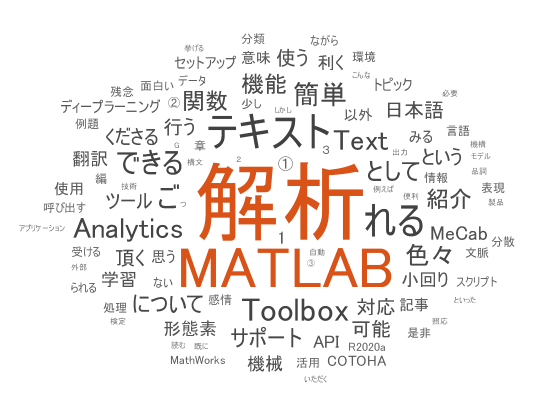

ans =   WordCloudChart のプロパティ:

           WordData: [1×467 string]
           SizeData: [1×467 double]
    MaxDisplayWords: 100

  すべてのプロパティ を表示


wordcloud(documents)